# Lexture 5: Plotting FRF matrices

*The code below shows you how to create the bode plot from the FRF. In practice, the bode() command is the most efficient way to accomplish this.*

- Calculate FRF matrix using the inverse dynamic stiffness matrix.

- Calculate FRF matrix using the principle of modal superposition.

Welcome! In this script, we are going to determine and plot Frequency Response Functions (FRFs) for a cart-pendulum mechanical system.

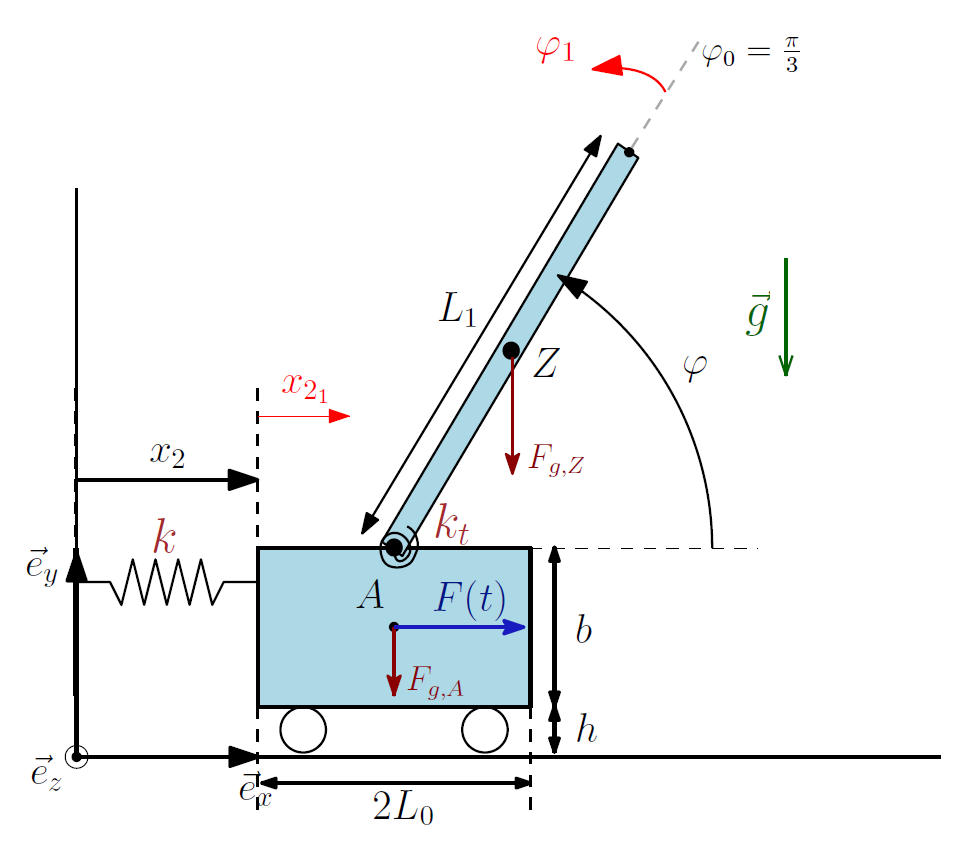

The generalized coordinates are chosen as$\;q=\left\lbrack \begin{array}{c}
x_2 \\
\varphi \;
\end{array}\right\rbrack$.

The parameters of the model are:

- $m$ = 10               [kg]

- $M$ = 2                [kg]

- $L_1$ = 1                [m]

- $g$ = 9.8             $\left\lbrack \frac{m}{s^2 }\right\rbrack$

- $k$ = 1000           [N/m]

- $k_t$ = $3\frac{{\textrm{MgL}}_1 }{2\pi \;}$      [Nm/rad]

## Mass and Stiffness matrices

clc; clear all; close all;

% Parameter values:
m = 10;
M = 2;
L_1 = 1;
g = 9.8;
k = 1000;
k_t = 3*M*g*L_1/2/pi;

% The Mass and Stiffness matrices can be derived from Lagrange Equation and are given here:
M_0 = [m+M,               -sqrt(3)*M*L_1/4;
       -sqrt(3)*M*L_1/4,  1*M*L_1^2/3];
K_0 = [k, 0;
       0, k_t-sqrt(3)/4*M*g*L_1];

## FRF 

The FRF of this linearized system, evaluated at frequency $\Omega$, is obtained by using:

$\mathit{\mathbf{H}}\left(\Omega \;\right)={\left\lbrack -\Omega \;{\;}^2 {\mathit{\mathbf{M}}}_{0\;} +{\mathit{\mathbf{K}}}_{0\;} \right\rbrack }^{-1}$ .

For plotting, we plot both the magnitude $|{\mathit{\mathbf{H}}}_{i,j} |$and phase $\angle \left({\mathit{\mathbf{H}}}_{i,j} \right)$ of the transfer function ${\mathit{\mathbf{H}}}_{i,j}$, where $j$ indicates from which input, and $i$ indicates to which output. Thus, ${\mathit{\mathbf{H}}}_{12}$ is the transfer function from the second force to the first generalized coordinate.

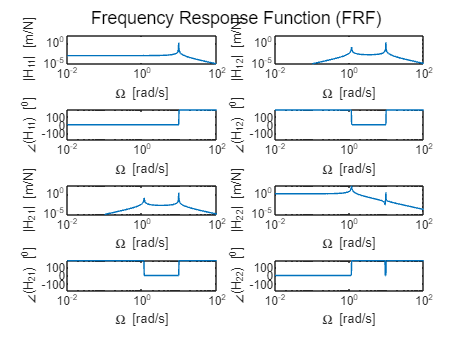

Omega = logspace(-2, 2, 500);  % vector containing the frequencies at which the FRFs will be evaluated
H = zeros(size(M_0, 1), size(M_0, 2), length(Omega));
% Here, we have initialized the FRF matrix H as a 3-dimensional matrix. 
% The first and second axes constitute the matrix part (i.e., from which force to which output the transfer tells us something)
% The third axis is used to store the information for all evaluated frequencies Omega.
% Consequently, you can view this 3D matrix as multiple 2D matrices that change along the 3rd (frequency) axis.
for i = 1:length(Omega)  % FRF is calculated for each evaluated frequency 'Om'
    Om = Omega(i);
    H(:, :, i) = inv(-Om^2*M_0+K_0);
end

% Plotting:
figure
for i_in = 1:2
    for i_out = 1:2
        subplot(4, 2, 4*(i_out-1)+i_in)
        loglog(Omega, abs(squeeze(H(i_out, i_in, :))))
        xlim([Omega(1), Omega(end)])
        ylim([10^-5 10^2]);
        xlabel("\Omega [rad/s]")
        ylabel(sprintf("|H_{%d%d}| [m/N]", i_out, i_in));

        subplot(4, 2, 4*(i_out-1)+i_in+2)
        semilogx(Omega, (180/pi)*(angle(squeeze(H(i_out, i_in, :)))))
        ylabel(sprintf("\\angle(H_{%d%d}) [^0]", i_out, i_in));
        xlabel("\Omega [rad/s]")
        xlim([Omega(1), Omega(end)])
        ylim([-180 180])
    end
end

sgtitle("Frequency Response Function (FRF)")


Note: The peaks in this FRF should actually go to infinity (because there is no damping in the system). Numerical rounding in the plot causes the peaks to appear finite. 

Note that the magnitude of the off-diagonal entries of $\mathit{\mathbf{H}}$ (${\mathit{\mathbf{H}}}_{12}$ and ${\mathit{\mathbf{H}}}_{21}$) at low frequencies is approximately zero, i.e.,


$$H\left(\Omega \;\right)\approx \left\lbrack \begin{array}{cc}
H_{11} \left(\Omega \;\right) & 0\\
0 & H_{22} \left(\Omega \;\right)
\end{array}\right\rbrack ,\;\;\;\;\;\textrm{for}\;\;\Omega \to 0\ldotp$$


This indicates that the system is (approximately) uncoupled at low frequencies and can thus be regarded as two separate Single Input Single Output systems at these low frequencies:

$\begin{array}{l}
\hat{q_1 } \;\approx H_{11} \left(\Omega \;\right)\hat{Q_1 } \\
\hat{q_2 } \approx H_{22} \left(\Omega \;\right)\hat{Q_2 } 
\end{array}$ ,     $\textrm{for}\;\Omega \to 0,$ 

where $\hat{Q_j }$ is the $j$th force (in frequency domain), and $\hat{q_i }$ is the $i$th output (in frequency domain).

## FRF using modal superposition

Alternatively, the FRF can be calculated using the principle of modal superposition which incorporates the eigenmodes and eigenfrequencies:


$$\mathit{\mathbf{H}}\left(\Omega \;\right)=\sum_{r=1}^n \left\lbrack \frac{u_r \;u_r^{\top } }{{m^* }_r \;\left(\omega_r^2 -\Omega^2 \right)\;}\right\rbrack ,$$


where $u_r$ and ${\omega \;}_r$ are the $r$th eigenmode and eigenfrequency, respectively. Furthermore, ${m^* }_r$ is the modal mass corresponding to the $r$th mode and $n$ is the number of eigenmodes. Note that this approach does not require the calculation of an inverse for each evaluated frequency $\Omega$.

First, the eigenmodes, eigenfrequencies, and modal masses are calculated (this has been explained in Lectures 4 and 5). Note that the modal masses are the entries on the diagonal of the modal mass matrix, which is obtained by diagonalizing the mass matrix using the eigenmodes: 


$$\left\lbrack \begin{array}{cccc}
{m^* }_1  & 0 & \cdots  & 0\\
0 & {m^* }_2  & \ddots  & 0\\
\vdots  & \ddots  & \ddots  & 0\\
0 & 0 & 0 & {m^* }_n 
\end{array}\right\rbrack ={\mathit{\mathbf{U}}}^{\top \;} {\mathit{\mathbf{M}}}_0 \;\mathit{\mathbf{U}},$$


or, in uncoupled form:

${m^* }_r =u_r^{\top \;} {\mathit{\mathbf{M}}}_0 {\;u}_r \;,\;\;\mathrm{for}\;r=1,2,\ldotp \ldotp \ldotp ,n$.

[U_unsorted,lambda] = eig(M_0\K_0);         % solve eigenvalue problem for eigenmatrix (U) and (squared) eigenvalues matrix (lambda)   
[w, order_w] = sort(sqrt(diag(lambda)));    % solve for eigenfrequencies (rad/s) and sort from small to large
U = U_unsorted(:, order_w);                 % make sure that eigenmodes are ordered equivalently to their corresponding eigenfrequencies (from low to high) 
m_r = diag(transpose(U)*M_0*U);             % calculate diagonal entries of modal mass matrix (kg)

Now, the FRF is calculated using modal superposition.

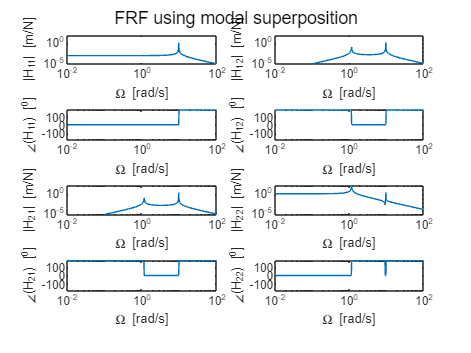

H_modal = zeros(size(M_0, 1), size(M_0, 2), length(Omega));
% Again, we have initialized the FRF matrix H as a 3-dimensional matrix. 
% The first and second axes constitute the matrix part (i.e., from which force to which output the transfer tells us something)
% The third axis is used to store the information for all evaluated frequencies Omega.
% Consequently, you can view this 3D matrix as multiple 2D matrices that change along the 3rd (frequency) axis.
for i = 1:length(Omega)
    Om = Omega(i);
    for j = 1:size(U, 2)  % FRF is summed, for each evaluated frequency 'Om', over all (in this case 2) eigenmodes
        H_modal(:, :, i) = H_modal(:, :, i) + (U(:, j)*transpose(U(:, j)))/(m_r(j)*(w(j)^2-Om^2));
    end
end

% Plotting:
figure
for i_in = 1:2
    for i_out = 1:2
        subplot(4, 2, 4*(i_out-1)+i_in)
        loglog(Omega, abs(squeeze(H_modal(i_out, i_in, :))))
        xlim([Omega(1), Omega(end)])
        ylim([10^-5 10^2]);
        xlabel("\Omega [rad/s]")
        ylabel(sprintf("|H_{%d%d}| [m/N]", i_out, i_in));

        subplot(4, 2, 4*(i_out-1)+i_in+2)
        semilogx(Omega, (180/pi)*(angle(squeeze(H_modal(i_out, i_in, :)))))
        ylabel(sprintf("\\angle(H_{%d%d}) [^0]", i_out, i_in));
        xlabel("\Omega [rad/s]")
        xlim([Omega(1), Omega(end)])
        ylim([-180 180])
    end
end
sgtitle("FRF using modal superposition")

Having calculated the FRFs in two different ways, we see that the plotted results are equivalent, as is to be expected.